# Greybox Identification - Scenario Analysis Implementation 

## **Plant layout**

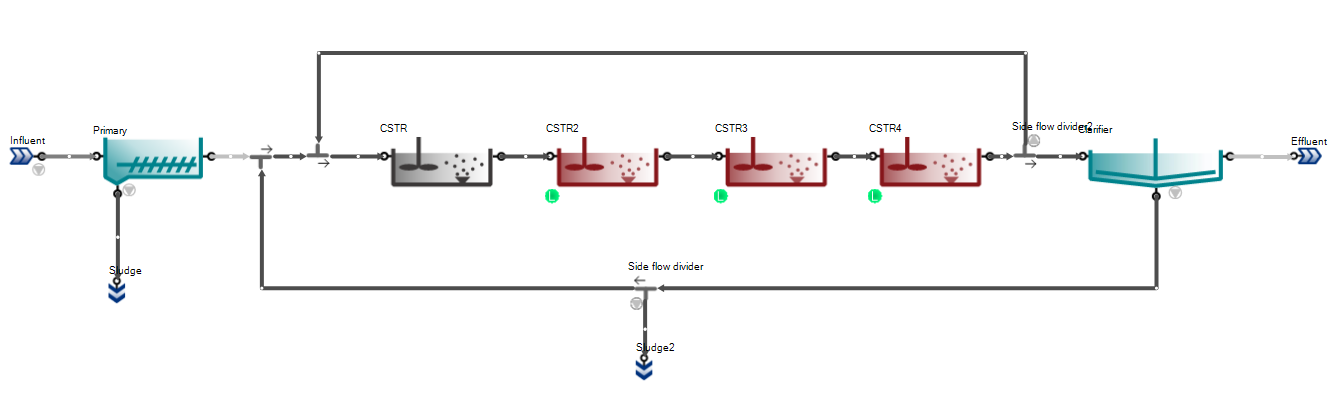

## Greybox Model Information

### Input(Disturbance) signals (n = 5) 

u_1(t) =  QPE                            Primary effluent volumetric flow rate, m3/d,          pipe 2

u_2(t) =  QRAS                         Recirculation sludge volumetric flow rate, m3/d    pipe12

u_3(t) =  QMLE                         Primary effluent volumetric flow rate, m3/d           pipe14       

u_4(t) = TKN                             Influent TKN concentration, g/m3                         No use

u_5(t) = MLSS                           Mixed Liquor concentration, kg/m3                  

Note:  Qtot = QPE + QRAS + QMLE                                                                      pipe 5       

### Input (Controllable) signals (n = 3) 

u_6(t) = SO1                             DO setpoint of the first tank, g/m3

u_7(t) = SO2                             DO setpoint of the first tank, g/m3

u_8(t) = SO3                             DO setpoint of the first tank, g/m3

### States (n=3)

x_1(t) = SNH1                              SNH concentration in the first AER tank, g/m3

x_2(t) = SNH2                              SNH concentration in the second AER tank, g/m3

x_3(t) = SNH3                              SNH concentration in the third AER tank, g/m3

### Output signals (n=3)

y(t) = eye(3) * [x_1(t);                              SNH concentration in the first AER tank, g/m3

                       x_2(t);                              SNH concentration in the second AER tank, g/m3

                       x_3(t)]                              SNH concentration in the third AER tank, g/m3

### Parameters (n = 7) 

r                                                observed nitrification rate , g/m3/d                                                       Free + negative 

V                                               reactor volume of each tank, m3                                                           Fixed = 2000

KNH                                          half-saturation coefficient of SNH, g/m3                                                Fixed = 0.5

KOA1                                        half-saturation coefficient of the first tank ,    g/m3                                Free, positive 

KOA2                                        half-saturation coefficient of the second tank ,    g/m3                          Free, positive 

KOA3                                        half-saturation coefficient of the third tank ,    g/m3                               Free, positive 

fr                                               fraction of SNH in TKN, g/m3                                                                Fixed = 0.7

### Equation 


$$\frac{\textrm{dSNH1}\;}{\textrm{dt}}=\frac{1}{V}\left(Q_{\textrm{PE}} \cdot \textrm{TKN}\cdot \alpha \;+Q_{\textrm{RAS}} \cdot \;\textrm{SNH3}+Q_{\textrm{MLE}} \cdot \;\textrm{SNH3}-\left(Q_{\textrm{PE}} +Q_{\textrm{RAS}} +Q_{\textrm{MLE}} \right)\cdot \textrm{SNH1}\;\right)+r\;\frac{\textrm{SO1}}{\textrm{SO1}+\textrm{KOA1}}\;$$



$$\frac{\textrm{dSNH2}\;}{\textrm{dt}}=\frac{1}{V}\left(\left(Q_{\textrm{PE}} +Q_{\textrm{RAS}} +Q_{\textrm{MLE}} \right)\cdot \left(\textrm{SNH1}-\textrm{SNH2}\right)\;\right)+r\;\frac{\textrm{SNH2}}{\textrm{SNH2}+\textrm{KNH}}\;\frac{\textrm{SO2}}{\textrm{SO2}+\textrm{KOA2}}\;$$



$$\frac{\textrm{dSNH3}\;}{\textrm{dt}}=\frac{1}{V}\left(\left(Q_{\textrm{PE}} +Q_{\textrm{RAS}} +Q_{\textrm{MLE}} \right)\cdot \left(\textrm{SNH2}-\textrm{SNH3}\right)\;\right)+r\;\frac{\textrm{SNH3}}{\textrm{SNH3}+\textrm{KNH}}\;\frac{\textrm{SO3}}{\textrm{SO3}+\textrm{KOA3}}\;$$



$$y=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
\textrm{SNH1}\\
\textrm{SNH2}\\
\textrm{SNH3}
\end{array}\right\rbrack$$


## Non-linear Greybox Model Initialization 

clear; 
FileName      = 'MLE3Tanks_1r';                       % File describing the model structure.
Order         = [3 8 3];                           % Model orders [ny nu nx].

Parameters    = [-350; 2000; 0.5; 0.6; 0.4; 0.2 ;0.7];      % Initial parameters.
InitialStates = [4.5; 2; 0.5];                            % Initial value of the initial states.
Ts            = 0;                                 % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts,...
                'Name', 'nlgr_MLE',  ...
                'TimeUnit', 'days');
% Input setting             
nlgr.InputName = {'QPE'   ...  % u(1).
                  'QRAS'  ...  % u(2).
                  'QMLE'  ...  % u(3).
                  'TKN'   ...  % u(4).
                  'MLSS'  ...  % u(5). 
                  'SO1'   ...  % u(6).
                  'SO2'   ...  % u(7)
                  'SO3'};      % u(8).
nlgr.InputUnit = {'m3/d' 'm3/d' 'm3/d' 'g-N/m3' 'kg/m3' 'g/m3' 'g/m3' 'g/m3'};

% State setting 
nlgr = setinit(nlgr, 'Name', {'SNH1','SNH2','SNH3'});        % x.
nlgr = setinit(nlgr, 'Unit', {'g/m3','g/m3','g/m3'});
nlgr = setinit(nlgr, 'Fixed', {false,false,false});

% Output setting
nlgr.OutputName = {'SNH1','SNH2','SNH3'};                    % y.
nlgr.OutputUnit = {'g-N/m3','g-N/m3','g-N/m3'};


nlgr = setpar(nlgr, 'Name', {'Maximum nitrification rate r in all tanks'    ...   % r.
                             'Reactor volume of each tank'                  ...   % V.
                             'Half saturation of SNH'                       ...   % KNH.
                             'Half saturation of SO in tank 1'              ...   % KOA1. 
                             'Half saturation of SO in tank 2'              ...   % KOA2. 
                             'Half saturation of SO in tank 3'              ...   % KOA3. 
                             'frac SNH/TKN'});                                    % a.

nlgr = setpar(nlgr, 'Unit', {'g/m3/d' 'm^3' 'g/m3' 'g/m3' 'g/m3' 'g/m3' 'dimentionless'});

nlgr.Parameters(2).Fixed = true;    % Fix V.
nlgr.Parameters(7).Fixed = true;    % Fix  fraction


% Negative r 
nlgr.Parameters(1).Maximum = 0;  

% KOA KNH. lower bound 
nlgr.Parameters(3).Minimum = 0.3;  
nlgr.Parameters(4).Minimum = 0.5;  
nlgr.Parameters(5).Minimum = 0.3;  
nlgr.Parameters(6).Minimum = 0.1;  

% KOA KNH. upper bound
nlgr.Parameters(3).Maximum = 0.6;  
nlgr.Parameters(4).Maximum = 0.7;  
nlgr.Parameters(5).Maximum = 0.5;  
nlgr.Parameters(6).Maximum = 0.3;  

% Optimization setting 
opt = nlgreyestOptions('Display', 'on');
opt.SearchOptions.MaxIterations = 100;
opt.SearchOptions.StepTolerance = 1e-6;
opt.SearchMethod = 'lsqnonlin';

% Create a matrix to store R2 and NRMSE
eval_mat = nan(8,12);

## Scenario 1: Constant ammonia loading + Varying DO setpoint 

$\textrm{SO1},\;\textrm{SO2},\;\;\textrm{SO3}\in \left\lbrack 0\ldotp 5,3\right\rbrack$ random uniformly distributed


$$\textrm{QPE}=23743\;\frac{m^3 }{d}$$
 


$$\textrm{QRAS}=23400\;\frac{m^3 }{d}$$
 


$$\textrm{QMLE}=36000\;\frac{m^3 }{d}$$
 


$$\textrm{TKN}=56\ldotp 6\;\frac{\textrm{mg}-N}{L}$$
 

% load input data from xlsx file 
[z,ze,zv] = prepare_iddata('scenario1.xlsx');

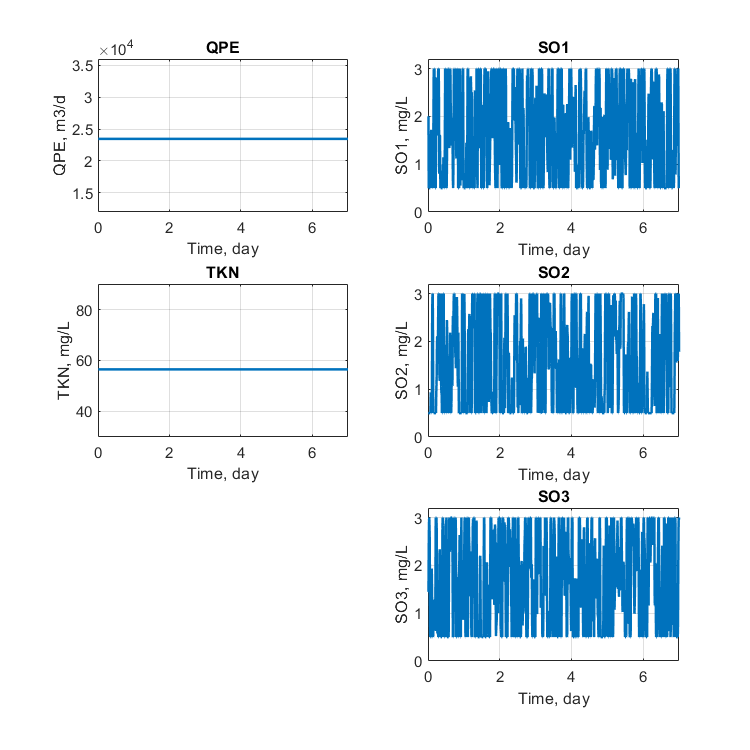

% Display Input
display_input(z,'.\Figures\Input_Scenario1.jpg');

% Estimiate the nlgr parameters 
nlgr_S1 = nlgreyest(ze,nlgr,opt);

     2        0.0414417         0.397             0.87


% Evaluate the result 
eval_mat(1,:) = eval_plot(nlgr_S1,ze,zv,'.\Figures\Scenario1.jpg');

## Scenario 2: Periodically varying ammnoia loadings  + Varying DO setpoint 

$\textrm{SO1},\;\textrm{SO2},\;\;\textrm{SO3}\in \left\lbrack 0\ldotp 5,3\right\rbrack$ random uniformly distributed, the same as scenario 1


$$\textrm{QRAS}=23400\;\frac{m^3 }{d}$$
 


$$\textrm{QMLE}=36000\;\frac{m^3 }{d}$$
 


$$\textrm{QPE}=\;23567\pm 2810\;\in \;\left\lbrack 18667,28348\right\rbrack \;\frac{m^3 }{d}\;\;\;$$



$$\textrm{TKN}=\;56\ldotp 6\pm \;6\ldotp 7\;\;\;\;\in \;\left\lbrack 37\ldotp 5,\;77\ldotp 6\right\rbrack \;\frac{\textrm{mg}-N}{L}$$


% load input data from xlsx file 
[z,ze,zv] = prepare_iddata('scenario2.xlsx');

%QPE = z.u(:,1);
%TKN = z.u(:,4);
%[min(QPE) max(QPE) mean(QPE) std(QPE)]
%[min(TKN) max(TKN) mean(TKN) std(TKN)]

% Display Input
display_input(z,'.\Figures\Input_Scenario2.jpg');


nlgr_S2 = nlgreyest(ze,nlgr,opt);

% Evaluate the result 
eval_mat(2,:) = eval_plot(nlgr_S2,ze,zv,'.\Figures\Scenario2.jpg');

## Scenario 3: Periodically varying ammnoia loadings  + Varying DO setpoint + 5% noise for all measurements(u & y)

The noise-free measurements are the same as Scenario 2

$\textrm{SO1},\;\textrm{SO2},\;\;\textrm{SO3}\in \left\lbrack 0\ldotp 5,3\right\rbrack$ random uniformly distributed, the same as scenario 1


$$\textrm{QRAS}=23400\;\frac{m^3 }{d}$$
 


$$\textrm{QMLE}=36000\;\frac{m^3 }{d}$$
 


$$\textrm{QPE}=\;23567\pm 2810\;\in \;\left\lbrack 18667,28348\right\rbrack \;\frac{m^3 }{d}\;\;\;$$



$$\textrm{TKN}=\;56\ldotp 6\pm \;6\ldotp 7\;\;\;\;\in \;\left\lbrack 37\ldotp 5,\;77\ldotp 6\right\rbrack \;\frac{\textrm{mg}-N}{L}$$


% load input data from xlsx file 
[z,ze,zv] = prepare_iddata('scenario2.xlsx');

% add noise to the training set ze while do nothing over zv
z_noise = z;
rng(0408);
for i = 1:size(z.u,2)
    z_noise.u(:,i) = z.u(:,i) + 0.1*randn(size(z.u(:,i)))*mean(z.u(:,i));
end

for i = 1:size(z.y,2)
    z_noise.y(:,i) = z.y(:,i) + 0.1*randn(size(z.y(:,i)))*mean(z.y(:,i));
end


% Display Input
display_input(z_noise,'.\Figures\Input_Scenario3.jpg');

% Estimiate the nlgr parameters 
total_num_points = size(z.u,1); 
train_evaluation_ratio = 0.5; 
n = floor(total_num_points*train_evaluation_ratio);
ze_noise = z_noise(1:n);
nlgr_S3 = nlgreyest(ze_noise,nlgr,opt);

% Evaluate the result 
eval_mat(3,:) = eval_plot(nlgr_S3,ze,zv,'.\Figures\Scenario3.jpg');

### Scenario 4: Periodically varying ammnoia loadings  + Varying DO setpoint + Temperature drop from 20 to 15 C

% load input data from xlsx file 
[z,ze,zv] = prepare_iddata('scenario4.xlsx');

% Display Input
display_input(z,'.\Figures\Input_Scenario4.jpg');
hold on;
subplot(3,2,5);
time = z.SamplingInstants;
temp = 20*ones(size(time));
temp(time>3) = 19;
temp(time>3.5) = 18;
temp(time>4) = 15;
plot(time, temp,'linewidth',1.5,'color','red');
grid on;
box on;
xlim([0 7]);
ylim([12 22]);
ylabel('Temperature, C');
xlabel('Time, day');
saveas(gcf,'.\Figures\Input_Scenario4.jpg'); 

% Estimiate the nlgr parameters 
nlgr_S4 = nlgreyest(ze,nlgr,opt);

% Evaluate the result 
eval_mat(4,:) = eval_plot(nlgr_S4,ze,zv,'.\Figures\Scenario4.jpg');

% Reestimiate the nlgr parameters based on the second half 
nlgr_S4_15 = nlgreyest(zv,nlgr_S4,opt);
eval_mat(5,:) = eval_plot(nlgr_S4_15,ze,zv,'.\Figures\Scenario4_star.jpg');

### Scenario 5: Periodically varying ammnoia loadings  + Varying DO setpoint + SRT(avg) drop from 7 to 4 days

% load input data from xlsx file 
[z,ze,zv] = prepare_iddata('scenario5.xlsx');


% Display Input
display_input(z,'.\Figures\Input_Scenario5.jpg');
hold on;
subplot(3,2,5);
excel_name = 'scenario5.xlsx';
%%%%%%%%%%%% load SNH and TSS
opts = spreadsheetImportOptions("NumVariables", 2);
% Specify sheet and range
opts.Sheet = "SRT";
opts.DataRange = "B5:C1013";

% Specify column names and types
opts.VariableNames = ["Time","SRT"];
opts.VariableTypes = ["double","double"];

% Import the data
state = readtable(excel_name, opts, "UseExcel", false);
Time = state{:,"Time"};
SRT = state{:,"SRT"};

plot(Time, SRT,'linewidth',1.5,'color','red');
grid on;
box on;
xlim([0 7]);
ylim([0 9]);
ylabel('SRT, days');
xlabel('Time, day');
saveas(gcf,'.\Figures\Input_Scenario5.jpg'); 

% Estimiate the nlgr parameters 
nlgr_S5 = nlgreyest(ze,nlgr,opt);

% Evaluate the result 
eval_mat(6,:) = eval_plot(nlgr_S5,ze,zv,'.\Figures\Scenario5.jpg');

% Reestimiate the nlgr parameters based on the second half 
nlgr_S5_15 = nlgreyest(zv,nlgr_S5,opt);
eval_mat(7,:) = eval_plot(nlgr_S5_15,ze,zv,'.\Figures\Scenario5_star.jpg');

## Scenario 6: Periodically varying ammnoia loadings  + Varying DO setpoint within 10% of their nominal values

$\begin{array}{l}
\textrm{SO1}=\;1\ldotp 5\pm \;0\ldotp 1\;\;\;\;\in \;\left\lbrack 1\ldotp 2,\;1\ldotp 8\right\rbrack \;\frac{\textrm{mg}}{L}\\
\textrm{SO2}=\;1\ldotp 0\pm \;0\ldotp 1\;\;\;\;\in \;\left\lbrack 0\ldotp 6,\;1\ldotp 4\right\rbrack \;\frac{\textrm{mg}}{L}\;\\
\textrm{SO3}=\;0\ldotp 5\pm \;0\ldotp 1\;\;\;\;\in \;\left\lbrack 0\ldotp 2,\;0\ldotp 9\right\rbrack \;\frac{\textrm{mg}}{L}
\end{array}$ random uniformly distributed


$$\textrm{QRAS}=23400\;\frac{m^3 }{d}$$
 


$$\textrm{QMLE}=36000\;\frac{m^3 }{d}$$
 


$$\textrm{QPE}=\;23567\pm 2810\;\in \;\left\lbrack 18667,28348\right\rbrack \;\frac{m^3 }{d}\;\;\;$$



$$\textrm{TKN}=\;56\ldotp 6\pm \;6\ldotp 7\;\;\;\;\in \;\left\lbrack 37\ldotp 5,\;77\ldotp 6\right\rbrack \;\frac{\textrm{mg}-N}{L}$$


% load input data from xlsx file 
[z,ze,zv] = prepare_iddata('scenario6.xlsx');

% SO1 = z.u(:,6);
% SO2 = z.u(:,7);
% SO3 = z.u(:,8);
% [min(SO1) max(SO1) mean(SO1) std(SO1)]
% [min(SO2) max(SO2) mean(SO2) std(SO2)]
% [min(SO3) max(SO3) mean(SO3) std(SO3)]

% Display Input
display_input(z,'.\Figures\Input_Scenario6.jpg');

% Estimiate the nlgr parameters 
nlgr_S6 = nlgreyest(ze,nlgr,opt);

% Evaluate the result 
eval_mat(8,:) = eval_plot(nlgr_S6,ze,zv,'.\Figures\Scenario6.jpg');
return;

## Scenario 7: Periodically varying ammnoia loadings  + Controller in place

$\begin{array}{l}
\textrm{SO1}=\;1\ldotp 14\pm \;0\ldotp 14\;\;\;\;\in \;\left\lbrack 1,\;1\ldotp 65\right\rbrack \;\frac{\textrm{mg}}{L}\\
\textrm{SO2}=\;0\ldotp 32\pm \;0\ldotp 12\;\;\;\;\in \;\left\lbrack 0\ldotp 20,\;0\ldotp 86\right\rbrack \;\frac{\textrm{mg}}{L}\;\\
\textrm{SO3}=\;0\ldotp 33\pm \;0\ldotp 14\;\;\;\;\in \;\left\lbrack 0\ldotp 20,\;0\ldotp 90\right\rbrack \;\frac{\textrm{mg}}{L}
\end{array}$ random uniformly distributed


$$\textrm{QRAS}=23400\;\frac{m^3 }{d}$$
 


$$\textrm{QMLE}=36000\;\frac{m^3 }{d}$$
 


$$\textrm{QPE}=\;23567\pm 2810\;\in \;\left\lbrack 18667,28348\right\rbrack \;\frac{m^3 }{d}\;\;\;$$



$$\textrm{TKN}=\;56\ldotp 6\pm \;6\ldotp 7\;\;\;\;\in \;\left\lbrack 37\ldotp 5,\;77\ldotp 6\right\rbrack \;\frac{\textrm{mg}-N}{L}$$


% load input data from xlsx file 
[z,ze,zv] = prepare_iddata('scenario7.xlsx');
z_noise = z;
rng(0408);


% SO1 = z.u(:,6);
% SO2 = z.u(:,7);
% SO3 = z.u(:,8);
% [min(SO1) max(SO1) mean(SO1) std(SO1)]
% [min(SO2) max(SO2) mean(SO2) std(SO2)]
% [min(SO3) max(SO3) mean(SO3) std(SO3)]

% Display Input
display_input(z,'.\Figures\Input_Scenario7.jpg');

% Estimiate the nlgr parameters 
% Optimization setting 
% Optimization setting 
opt = nlgreyestOptions('Display', 'on');
opt.SearchOptions.MaxIterations = 100;
opt.SearchOptions.StepTolerance = 1e-6;
opt.SearchMethod = 'lsqnonlin';
opt.OutputWeight = diag([0.1,10,100]);
% Estimiate the nlgr parameters 
nlgr_S7 = nlgreyest(ze,nlgr,opt);

% Evaluate the result 
eval_plot(nlgr_S7,ze,zv,'.\Figures\Scenario7.jpg');

% Write all parameter values in an Excel table 
nlgr_list = {nlgr_S1,nlgr_S2,nlgr_S3,nlgr_S4,nlgr_S4_15,nlgr_S5,nlgr_S5_15,nlgr_S6,nlgr_S7};
store_param = nan(9,5);
    for i =1:length(nlgr_list)
        temp= nlgr_list{i};
        store_param(i,1) = temp.Parameters(1).Value;
        store_param(i,2) = temp.Parameters(3).Value;
        store_param(i,3) = temp.Parameters(4).Value;
        store_param(i,4) = temp.Parameters(5).Value;
        store_param(i,5) = temp.Parameters(6).Value;
    end
